# Broad Cluster Growth Types

We see approximately four different types of growth:

(i) clusters do not form (mass-averaged cluster size remains <2 for all time)

(ii) clusters form slowly to an equilibrium value on the time scale of the simulation

(iii) clusters continue growing over the entire time scale of the simulation (really this is just a different time scale version of (ii))

(iv) A full spanning cluster rapidly forms, usually within the first 100 time steps of simulation

(v) anomalous growth -- one demonstration of a lag phase, one that basically just stays at the same size the whole way through (which is really a subset of (ii) with poor initial conditions)

First let's look at a very qualitative analysis of this.

bbs = 2;
aas = 5;
scs = 5;
ctypemat = zeros(bbs*aas*scs+5,6); %AA, SC, BB, approx look, rad, concentration (molecules/nm^3)
row = 1;
for bb = [0, 0.01]
    for aa = [0, 0.37,1.85,3.7,7.4]
        for sc = [0,0.2,2,4,10]
            ctypemat(row,1) = aa;
            ctypemat(row,2) = sc;
            ctypemat(row,3) = bb;
            ctypemat(row,5) = 0.5;
            ctypemat(row,6) = 0.027;
            row = row+1;
        end
    end
end
%extras from non-full runs, if necessary
ctypemat(row,1) = 1.85;
ctypemat(row,2) = 2;
ctypemat(row,3) = 0;
ctypemat(row,5) = 0.5;
ctypemat(row,6) = 0.0027;
row = row + 1;
ctypemat(row,1) = 0;
ctypemat(row,2) = 0;
ctypemat(row,3) = 4;
ctypemat(row,5) = 0.5;
ctypemat(row,6) = 0.027;
row = row + 1;
ctypemat(row,1) = 1.85;
ctypemat(row,2) = 2;
ctypemat(row,3) = 1;
ctypemat(row,5) = 0.5;
ctypemat(row,6) = 0.027;
row = row + 1;
ctypemat(row,1) = 1.85;
ctypemat(row,2) = 2;
ctypemat(row,3) = 4;
ctypemat(row,5) = 0.5;
ctypemat(row,6) = 0.027;
row = row + 1;
ctypemat(row,1) = 1.85;
ctypemat(row,2) = 2;
ctypemat(row,3) = 0;
ctypemat(row,5) = 0.25;
ctypemat(row,6) = 0.027;
ctypemat(:,4) = [0;0;0;1;2;0;0;2;2;2;2;2;3;3;3;1;1;3;3;3;1;4;3;3;3;0;0;1;2;2;0;0;4;3;3;2;1;2;3;3;1;2;2;3;3;1;1;2;3;3;1;1;1;1;1];

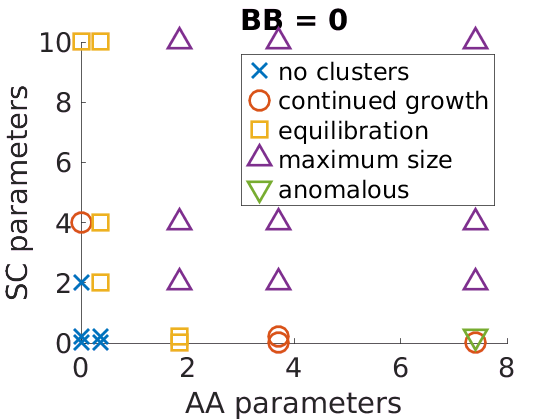

%plot for aa and sc parameters
saveloc = '/home/rachael/Dropbox/Images/Presentations/Research-11-8-17';
figure()
hold on
i1 = find(ctypemat(1:25,4) == 0);
plot(ctypemat(i1,1),ctypemat(i1,2),'x','markersize',15,'linewidth',2)
i1 = find(ctypemat(1:25,4) == 1);
plot(ctypemat(i1,1),ctypemat(i1,2),'o','markersize',15,'linewidth',2)
i1 = find(ctypemat(1:25,4) == 2);
plot(ctypemat(i1,1),ctypemat(i1,2),'s','markersize',15,'linewidth',2)
i1 = find(ctypemat(1:25,4) == 3);
plot(ctypemat(i1,1),ctypemat(i1,2),'^','markersize',15,'linewidth',2)
i1 = find(ctypemat(1:25,4) == 4);
plot(ctypemat(i1,1),ctypemat(i1,2),'v','markersize',15,'linewidth',2)
set(gca,'fontsize',20)
xlabel('AA parameters')
ylabel('SC parameters')
title('BB = 0')
legend('no clusters','continued growth','equilibration','maximum size','anomalous')

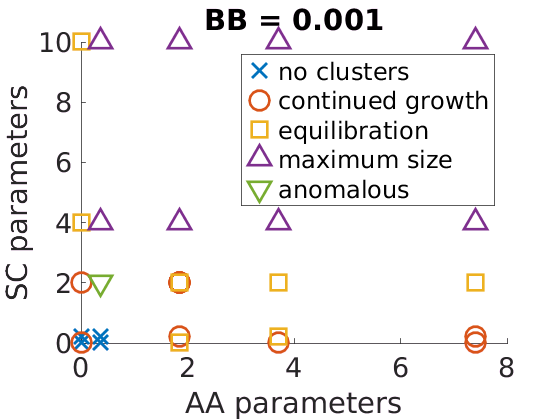


figure()
hold on
i1 = find(ctypemat(26:end,4) == 0)+25;
plot(ctypemat(i1,1),ctypemat(i1,2),'x','markersize',15,'linewidth',2)
i1 = find(ctypemat(26:end,4) == 1)+25;
plot(ctypemat(i1,1),ctypemat(i1,2),'o','markersize',15,'linewidth',2)
i1 = find(ctypemat(26:end,4) == 2)+25;
plot(ctypemat(i1,1),ctypemat(i1,2),'s','markersize',15,'linewidth',2)
i1 = find(ctypemat(26:end,4) == 3)+25;
plot(ctypemat(i1,1),ctypemat(i1,2),'^','markersize',15,'linewidth',2)
i1 = find(ctypemat(26:end,4) == 4)+25;
plot(ctypemat(i1,1),ctypemat(i1,2),'v','markersize',15,'linewidth',2)
set(gca,'fontsize',20)
xlabel('AA parameters')
ylabel('SC parameters')
title('BB = 0.001')
legend('no clusters','continued growth','equilibration','maximum size','anomalous')

## Read in Data

fileLocation = '/home/rachael/cluster/scratch/ramansbach/coarsegraining/hoomd/patchy/analyze/';
addpath('/home/rachael/Analysis_and_run_code/lab_notebook/CG_patchy/helper_fcns/');
fbase = 'mols10000_';
%if exist(Name, 'file') == 7 -- folder exists
[contactMatrix,opticalMatrix,alignedMatrix,ctypemat] = readClusteringData(fileLocation,fbase);

## Look at the final size, and the ratios of the contact/optical and contact/aligned final sizes

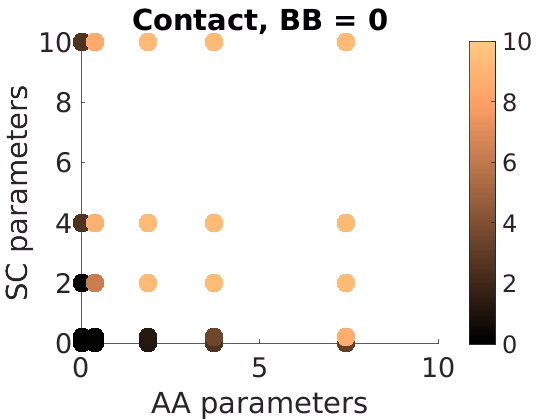

%contact final size

figure()
hold on
colormap copper
i1 = find(ctypemat(1:25,4) == 0);
%inot = find(ctypemat(1:25,4) ~= 0);
%plot(ctypemat(i1,1),ctypemat(i1,2),'rx','markersize',15,'linewidth',2)
inot = 1:25;
scatter(ctypemat(inot,1),ctypemat(inot,2),200,log(contactMatrix(inot,8)),'filled')
colorbar
caxis([0 10])
set(gca,'fontsize',20)
xlabel('AA parameters')
ylabel('SC parameters')
title('Contact, BB = 0')
saveas(gcf,[saveloc '/CCsizeBB0'],'pdf')
savefig([saveloc '/CCsizeBB0'])

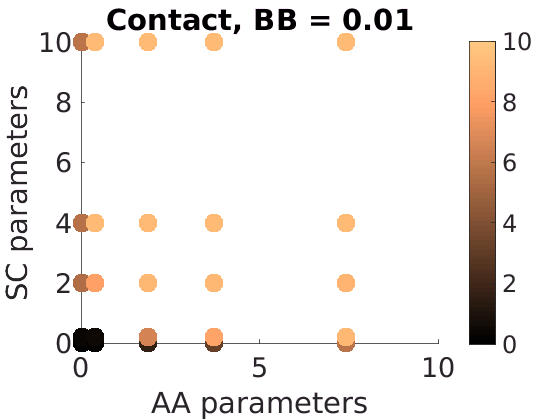


figure()
hold on
colormap copper
i1 = find(ctypemat(26:50,4) == 0)+25;
%inot = find(ctypemat(26:50,4) ~= 0)+25;
inot = 26:50;
%plot(ctypemat(i1,1),ctypemat(i1,2),'rx','markersize',15,'linewidth',2)
scatter(ctypemat(inot,1),ctypemat(inot,2),200,log(contactMatrix(inot,8)),'filled')
colorbar
caxis([0 10])
set(gca,'fontsize',20)
xlabel('AA parameters')
ylabel('SC parameters')
title('Contact, BB = 0.01')
saveas(gcf,[saveloc '/CCsizeBB01'],'pdf')
savefig([saveloc '/CCsizeBB01'])

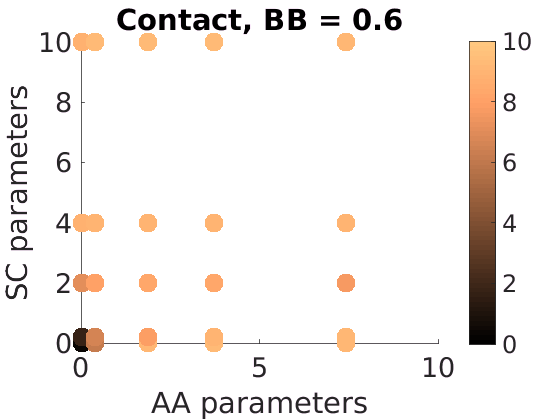


figure()
hold on
colormap copper
i1 = find(ctypemat(51:end,4) == 0)+50;
%inot = find(ctypemat(51:end,4) ~= 0)+50;
%plot(ctypemat(i1,1),ctypemat(i1,2),'rx','markersize',15,'linewidth',2)
inot = 51:75;
scatter(ctypemat(inot,1),ctypemat(inot,2),200,log(contactMatrix(inot,8)),'filled')
colorbar
caxis([0 10])
set(gca,'fontsize',20)
xlabel('AA parameters')
ylabel('SC parameters')
title('Contact, BB = 0.6')
saveas(gcf,[saveloc '/CCsizeBB06'],'pdf')
savefig([saveloc '/CCsizeBB06'])

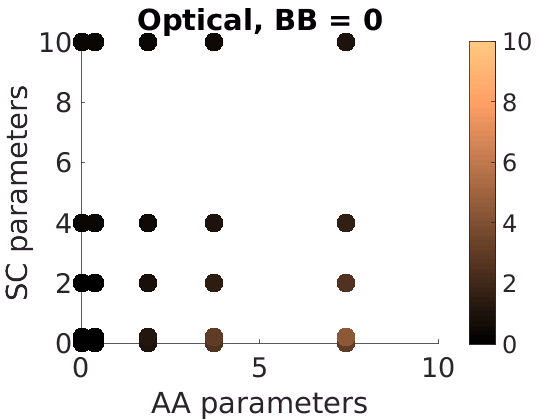


%optical final size
figure()
hold on
colormap copper
i1 = find(ctypemat(1:25,4) == 0);
%inot = find(ctypemat(1:25,4) ~= 0);
%plot(ctypemat(i1,1),ctypemat(i1,2),'rx','markersize',15,'linewidth',2)
inot = 1:25;
scatter(ctypemat(inot,1),ctypemat(inot,2),200,log(opticalMatrix(inot,8)),'filled')
colorbar
caxis([0 10])
set(gca,'fontsize',20)
xlabel('AA parameters')
ylabel('SC parameters')
title('Optical, BB = 0')
saveas(gcf,[saveloc '/OCsizeBB0'],'pdf')
savefig([saveloc '/OCsizeBB0'])

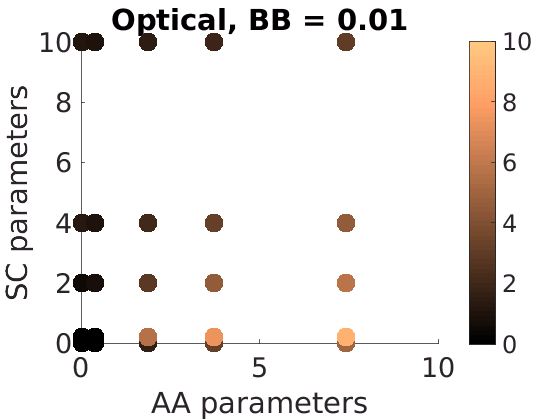


figure()
hold on
colormap copper
i1 = find(ctypemat(26:50,4) == 0)+25;
%inot = find(ctypemat(26:50,4) ~= 0)+25;
%plot(ctypemat(i1,1),ctypemat(i1,2),'rx','markersize',15,'linewidth',2)
inot = 26:50;
scatter(ctypemat(inot,1),ctypemat(inot,2),200,log(opticalMatrix(inot,8)),'filled')
colorbar
caxis([0 10])
set(gca,'fontsize',20)
xlabel('AA parameters')
ylabel('SC parameters')
title('Optical, BB = 0.01')
saveas(gcf,[saveloc '/OCsizeBB01'],'pdf')
savefig([saveloc '/OCsizeBB01'])

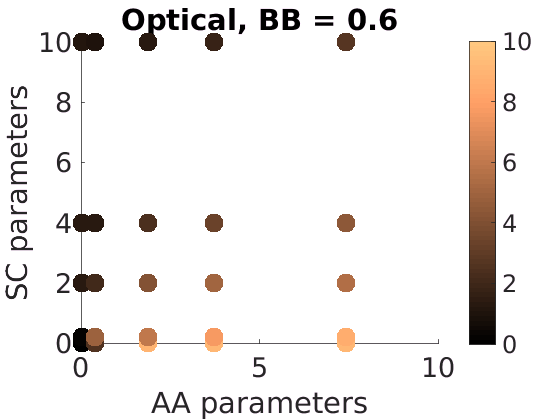


figure()
hold on
colormap copper
i1 = find(ctypemat(51:end,4) == 0)+50;
%inot = find(ctypemat(51:end,4) ~= 0)+50;
%plot(ctypemat(i1,1),ctypemat(i1,2),'rx','markersize',15,'linewidth',2)
inot = 51:75;
scatter(ctypemat(inot,1),ctypemat(inot,2),200,log(opticalMatrix(inot,8)),'filled')
colorbar
caxis([0 10])
set(gca,'fontsize',20)
xlabel('AA parameters')
ylabel('SC parameters')
title('Optical, BB = 0.6')
saveas(gcf,[saveloc '/OCsizeBB06'],'pdf')
savefig([saveloc '/OCsizeBB06'])

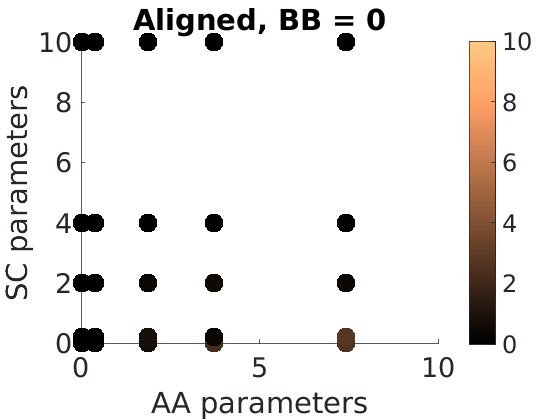


%aligned final size
figure()
hold on
colormap copper
i1 = find(ctypemat(1:25,4) == 0);
%inot = find(ctypemat(1:25,4) ~= 0);
%plot(ctypemat(i1,1),ctypemat(i1,2),'rx','markersize',15,'linewidth',2)
inot = 1:25;
scatter(ctypemat(inot,1),ctypemat(inot,2),200,log(alignedMatrix(inot,8)),'filled')
colorbar
caxis([0 10])
set(gca,'fontsize',20)
xlabel('AA parameters')
ylabel('SC parameters')
title('Aligned, BB = 0')
saveas(gcf,[saveloc '/ACsizeBB0'],'pdf')
savefig([saveloc '/ACsizeBB0'])

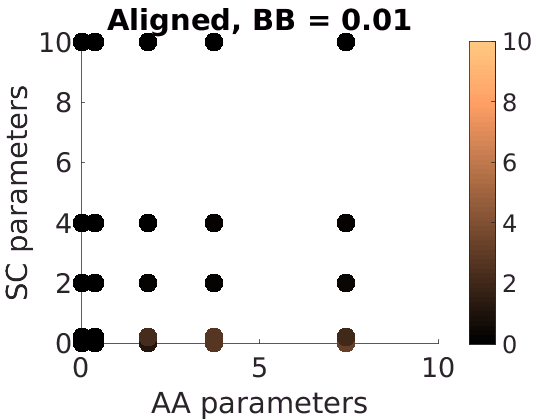


figure()
hold on
colormap copper
i1 = find(ctypemat(26:50,4) == 0)+25;
%inot = find(ctypemat(26:50,4) ~= 0)+25;
%plot(ctypemat(i1,1),ctypemat(i1,2),'rx','markersize',15,'linewidth',2)
inot = 26:50;
scatter(ctypemat(inot,1),ctypemat(inot,2),200,log(alignedMatrix(inot,8)),'filled')
colorbar
caxis([0 10])
set(gca,'fontsize',20)
xlabel('AA parameters')
ylabel('SC parameters')
title('Aligned, BB = 0.01')
saveas(gcf,[saveloc '/ACsizeBB01'],'pdf')
savefig([saveloc '/ACsizeBB01'])

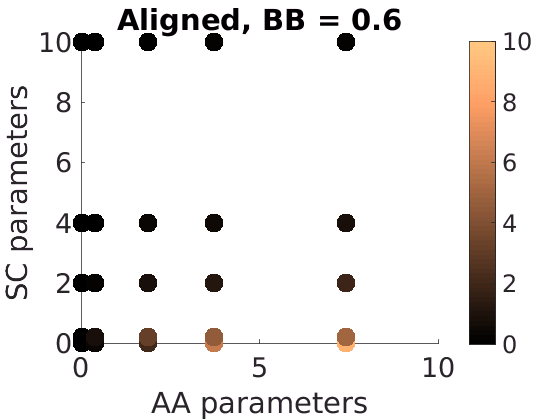


figure()
hold on
colormap copper
i1 = find(ctypemat(51:end,4) == 0)+50;
%inot = find(ctypemat(51:end,4) ~= 0)+50;
%plot(ctypemat(i1,1),ctypemat(i1,2),'rx','markersize',15,'linewidth',2)
inot = 51:75;
scatter(ctypemat(inot,1),ctypemat(inot,2),200,log(alignedMatrix(inot,8)),'filled')
colorbar
caxis([0 10])
set(gca,'fontsize',20)
xlabel('AA parameters')
ylabel('SC parameters')
title('Aligned, BB = 0.6')
saveas(gcf,[saveloc '/ACsizeBB06'],'pdf')
savefig([saveloc '/ACsizeBB06'])

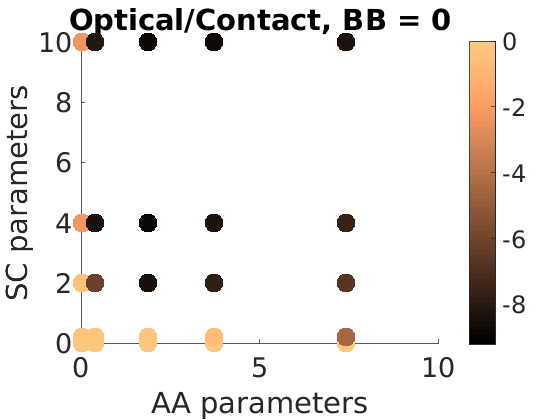

%optical/contact
figure()
hold on
colormap copper
i1 = find(ctypemat(1:25,4) == 0);
%inot = find(ctypemat(1:25,4) ~= 0);
%plot(ctypemat(i1,1),ctypemat(i1,2),'rx','markersize',15,'linewidth',2)
inot = 1:25;
scatter(ctypemat(inot,1),ctypemat(inot,2),200,log(opticalMatrix(inot,8)./contactMatrix(inot,8)),'filled')
colorbar
set(gca,'fontsize',20)
xlabel('AA parameters')
ylabel('SC parameters')
caxis([-9.2 0])
title('Optical/Contact, BB = 0')
saveas(gcf,[saveloc '/OCCsizeBB0'],'pdf')
savefig([saveloc '/OCCsizeBB0'])

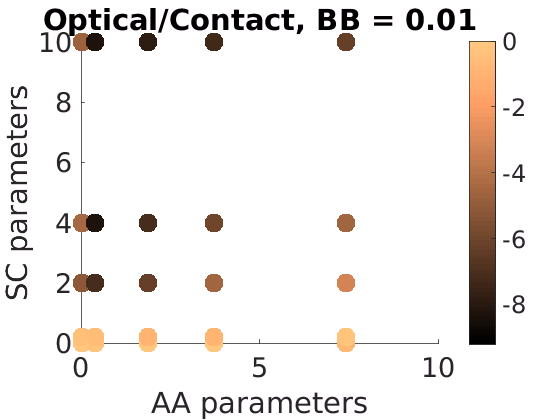


figure()
hold on
colormap copper
i1 = find(ctypemat(26:50,4) == 0)+25;
%inot = find(ctypemat(26:50,4) ~= 0)+25;
%plot(ctypemat(i1,1),ctypemat(i1,2),'rx','markersize',15,'linewidth',2)
inot = 26:50;
scatter(ctypemat(inot,1),ctypemat(inot,2),200,log(opticalMatrix(inot,8)./contactMatrix(inot,8)),'filled')
colorbar
set(gca,'fontsize',20)
xlabel('AA parameters')
ylabel('SC parameters')
caxis([-9.2 0])
title('Optical/Contact, BB = 0.01')
saveas(gcf,[saveloc '/OCCsizeBB01'],'pdf')
savefig([saveloc '/OCCsizeBB01'])

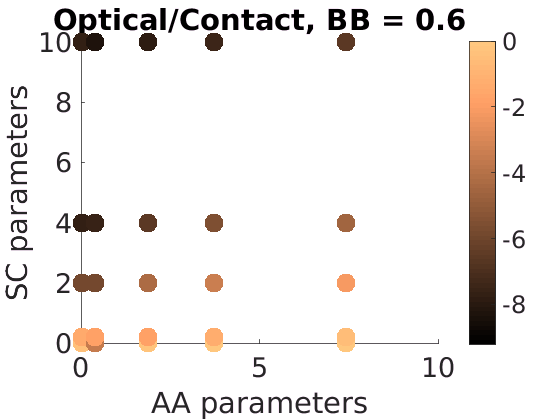


figure()
hold on
colormap copper
i1 = find(ctypemat(51:end,4) == 0)+50;
%inot = find(ctypemat(51:end,4) ~= 0)+50;
%plot(ctypemat(i1,1),ctypemat(i1,2),'rx','markersize',15,'linewidth',2)
inot = 51:75;
scatter(ctypemat(inot,1),ctypemat(inot,2),200,log(opticalMatrix(inot,8)./contactMatrix(inot,8)),'filled')
colorbar
caxis([-9.2 0])
set(gca,'fontsize',20)
xlabel('AA parameters')
ylabel('SC parameters')
title('Optical/Contact, BB = 0.6')
saveas(gcf,[saveloc '/OCCsizeBB06'],'pdf')
savefig([saveloc '/OCCsizeBB06'])

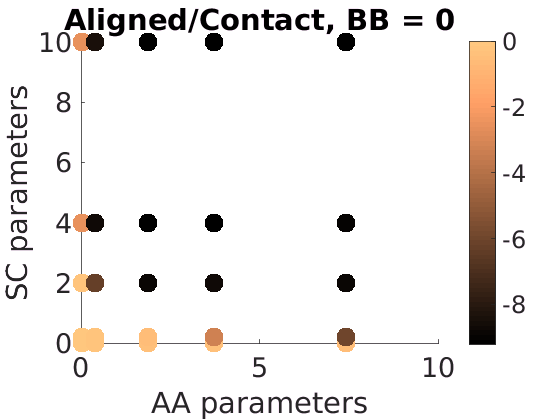


%aligned/contact
figure()
hold on
colormap copper
i1 = find(ctypemat(1:25,4) == 0);
%inot = find(ctypemat(1:25,4) ~= 0);
%plot(ctypemat(i1,1),ctypemat(i1,2),'rx','markersize',15,'linewidth',2)
inot = 1:25;
scatter(ctypemat(inot,1),ctypemat(inot,2),200,log(alignedMatrix(inot,8)./contactMatrix(inot,8)),'filled')
colorbar
caxis([-9.2 0])
set(gca,'fontsize',20)
xlabel('AA parameters')
ylabel('SC parameters')

title('Aligned/Contact, BB = 0')
saveas(gcf,[saveloc '/ACCsizeBB0'],'pdf')
savefig([saveloc '/ACCsizeBB0'])

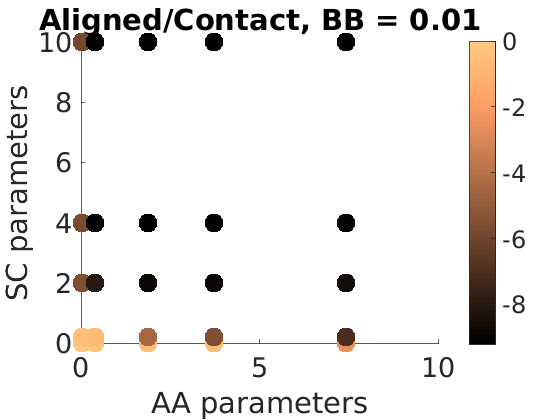


figure()
hold on
colormap copper
i1 = find(ctypemat(26:50,4) == 0)+25;
%inot = find(ctypemat(26:50,4) ~= 0)+25;
%plot(ctypemat(i1,1),ctypemat(i1,2),'rx','markersize',15,'linewidth',2)
inot = 26:50;
scatter(ctypemat(inot,1),ctypemat(inot,2),200,log(alignedMatrix(inot,8)./contactMatrix(inot,8)),'filled')
colorbar
caxis([-9.2 0])
set(gca,'fontsize',20)
xlabel('AA parameters')
ylabel('SC parameters')

title('Aligned/Contact, BB = 0.01')
saveas(gcf,[saveloc '/ACCsizeBB01'],'pdf')
savefig([saveloc '/ACCsizeBB01'])

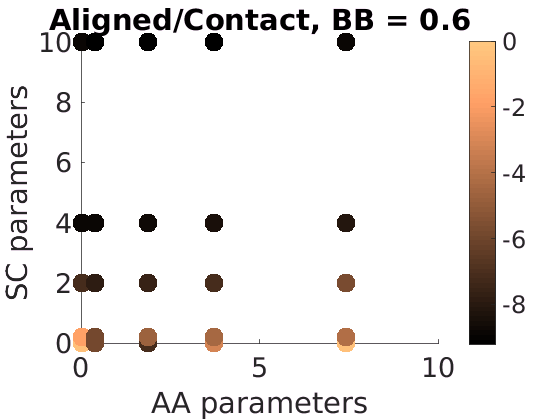


figure()
hold on
colormap copper
i1 = find(ctypemat(51:end,4) == 0)+50;
%inot = find(ctypemat(51:end,4) ~= 0)+50;
%plot(ctypemat(i1,1),ctypemat(i1,2),'rx','markersize',15,'linewidth',2)
inot = 51:75;
scatter(ctypemat(inot,1),ctypemat(inot,2),200,log(alignedMatrix(inot,8)./contactMatrix(inot,8)),'filled')
colorbar
caxis([-9.2 0])
set(gca,'fontsize',20)
xlabel('AA parameters')
ylabel('SC parameters')
title('Aligned/Contact, BB = 0.6')
saveas(gcf,[saveloc '/ACCsizeBB06'],'pdf')
savefig([saveloc '/ACCsizeBB06'])

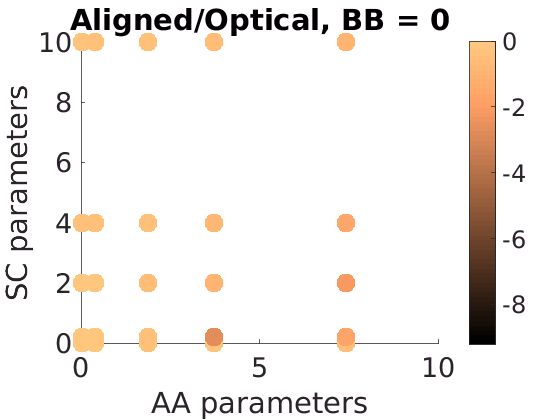


%aligned versus optical
figure()
hold on
colormap copper
i1 = find(ctypemat(1:25,4) == 0);
%inot = find(ctypemat(1:25,4) ~= 0);
%plot(ctypemat(i1,1),ctypemat(i1,2),'rx','markersize',15,'linewidth',2)
inot = 1:25;
scatter(ctypemat(inot,1),ctypemat(inot,2),200,log(alignedMatrix(inot,8)./opticalMatrix(inot,8)),'filled')
colorbar
caxis([-9.2 0])
set(gca,'fontsize',20)
xlabel('AA parameters')
ylabel('SC parameters')

title('Aligned/Optical, BB = 0')
saveas(gcf,[saveloc '/AOCsizeBB0'],'pdf')
savefig([saveloc '/AOCsizeBB0'])

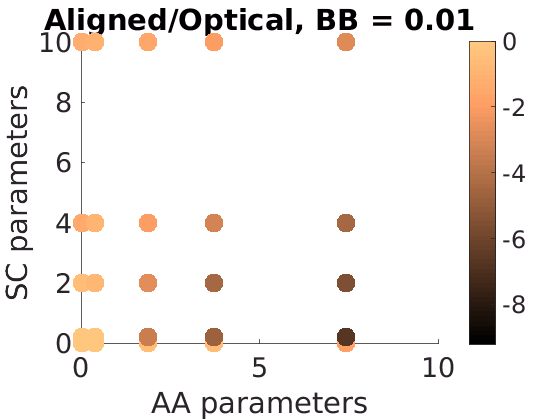


figure()
hold on
colormap copper
i1 = find(ctypemat(26:50,4) == 0)+25;
%inot = find(ctypemat(26:50,4) ~= 0)+25;
%plot(ctypemat(i1,1),ctypemat(i1,2),'rx','markersize',15,'linewidth',2)
inot = 26:50;
scatter(ctypemat(inot,1),ctypemat(inot,2),200,log(alignedMatrix(inot,8)./opticalMatrix(inot,8)),'filled')
colorbar
caxis([-9.2 0])
set(gca,'fontsize',20)
xlabel('AA parameters')
ylabel('SC parameters')

title('Aligned/Optical, BB = 0.01')
saveas(gcf,[saveloc '/AOCsizeBB01'],'pdf')
savefig([saveloc '/AOCsizeBB01'])

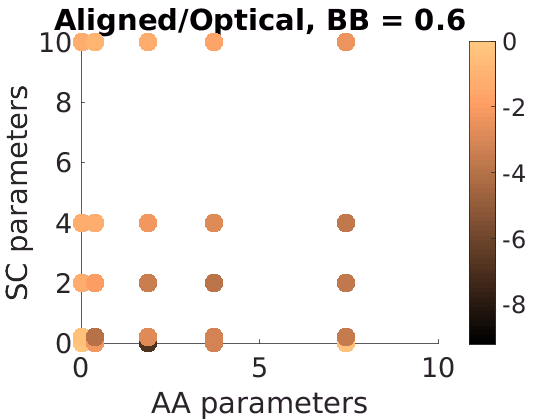


figure()
hold on
colormap copper
i1 = find(ctypemat(51:end,4) == 0)+50;
%inot = find(ctypemat(51:end,4) ~= 0)+50;
%plot(ctypemat(i1,1),ctypemat(i1,2),'rx','markersize',15,'linewidth',2)
inot = 51:75;
scatter(ctypemat(inot,1),ctypemat(inot,2),200,log(alignedMatrix(inot,8)./opticalMatrix(inot,8)),'filled')
colorbar
caxis([-9.2 0])
set(gca,'fontsize',20)
xlabel('AA parameters')
ylabel('SC parameters')
title('Aligned/Optical, BB = 0.6')
saveas(gcf,[saveloc '/AOCsizeBB06'],'pdf')
savefig([saveloc '/AOCsizeBB06'])

## Looking for patterns in the Smoluchowski exponents

Smoluchowski exponents near zero for contact cluster growth implies near-linear growth (independent of cluster size), which I predict should approximately be similar to eyeballed cluster type "continued growth".

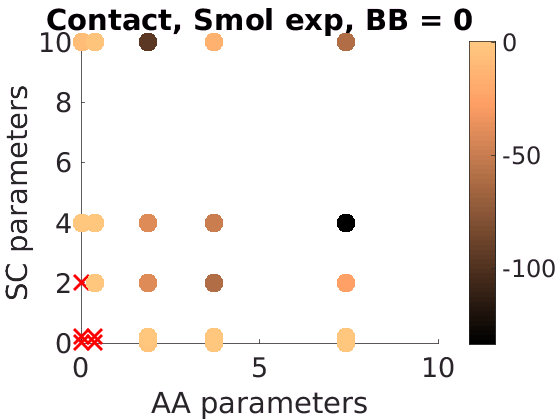

figure()
hold on
colormap copper
i1 = find(ctypemat(1:25,4) == 0);
inot = find(ctypemat(1:25,4) ~= 0);
plot(ctypemat(i1,1),ctypemat(i1,2),'rx','markersize',15,'linewidth',2)
scatter(ctypemat(inot,1),ctypemat(inot,2),200,contactMatrix(inot,5),'filled')
colorbar
set(gca,'fontsize',20)
xlabel('AA parameters')
ylabel('SC parameters')
title('Contact, Smol exp, BB = 0')
saveas(gcf,[saveloc '/CsmolexpBB0'],'pdf')
savefig([saveloc '/CsmolexpBB0'])

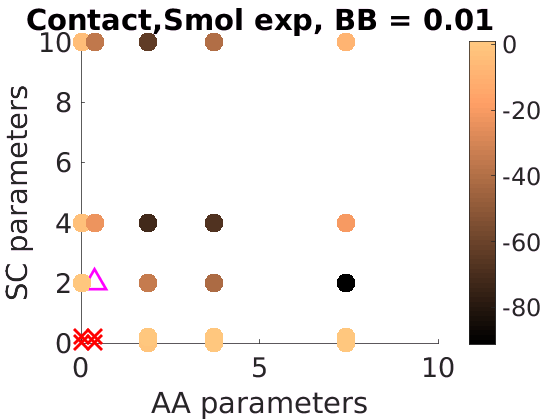


figure()
hold on
colormap copper
i1 = find(ctypemat(26:50,4) == 0)+25;
ianom = find(ctypemat(26:50,4)==4)+25;
inot = find((ctypemat(26:50,4) ~= 0)&(ctypemat(26:50,4)~=4))+25;
plot(ctypemat(i1,1),ctypemat(i1,2),'rx','markersize',15,'linewidth',2)
plot(ctypemat(ianom,1),ctypemat(ianom,2),'m^','markersize',15,'linewidth',2)
scatter(ctypemat(inot,1),ctypemat(inot,2),200,contactMatrix(inot,5),'filled')
colorbar
set(gca,'fontsize',20)
xlabel('AA parameters')
ylabel('SC parameters')
title('Contact,Smol exp, BB = 0.01')
saveas(gcf,[saveloc '/CsmolexpBB01'],'pdf')
savefig([saveloc '/CsmolexpBB01'])

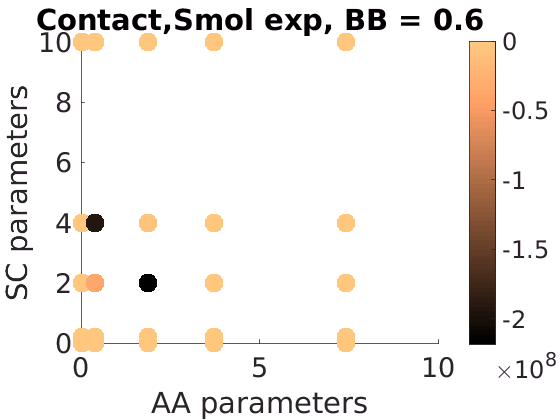


figure()
hold on
colormap copper
i1 = find(ctypemat(51:end,4) == 0)+50;
ianom = find(ctypemat(51:end,4)==4)+50;
inot = find((ctypemat(51:end,4) ~= 0)&(ctypemat(51:end,4)~=4))+50;
plot(ctypemat(i1,1),ctypemat(i1,2),'rx','markersize',15,'linewidth',2)
plot(ctypemat(ianom,1),ctypemat(ianom,2),'m^','markersize',15,'linewidth',2)
scatter(ctypemat(inot,1),ctypemat(inot,2),200,contactMatrix(inot,5),'filled')
colorbar
set(gca,'fontsize',20)
xlabel('AA parameters')
ylabel('SC parameters')
title('Contact,Smol exp, BB = 0.6')
saveas(gcf,[saveloc '/CsmolexpBB06'],'pdf')
savefig([saveloc '/CsmolexpBB06'])

For mu2 between -1 and 1, investigate the linear tc.  For other mu2, investigate the nonlinear tc.  First, look at each one, though.

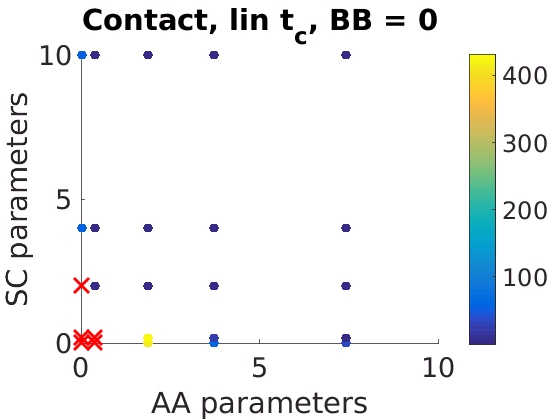

figure()
hold on
i1 = find(ctypemat(1:25,4) == 0);
inot = find(ctypemat(1:25,4) ~= 0);
plot(ctypemat(i1,1),ctypemat(i1,2),'rx','markersize',15,'linewidth',2)
scatter(ctypemat(inot,1),ctypemat(inot,2),50,contactMatrix(inot,1),'filled')
colorbar
set(gca,'fontsize',20)
xlabel('AA parameters')
ylabel('SC parameters')
title('Contact, lin t_c, BB = 0')

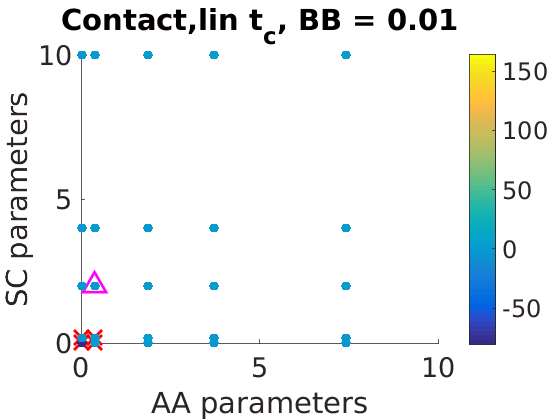


figure()
hold on
i1 = find(ctypemat(26:end,4) == 0)+25;
ianom = find(ctypemat(26:end,4)==4)+25;
inot = find((ctypemat(26:end,4) ~= 0)&(ctypemat(26:end,4)~=4))+25;
plot(ctypemat(i1,1),ctypemat(i1,2),'rx','markersize',15,'linewidth',2)
plot(ctypemat(ianom,1),ctypemat(ianom,2),'m^','markersize',15,'linewidth',2)
scatter(ctypemat(inot,1),ctypemat(inot,2),50,contactMatrix(inot,1),'filled')
colorbar
set(gca,'fontsize',20)
xlabel('AA parameters')
ylabel('SC parameters')
title('Contact,lin t_c, BB = 0.01')

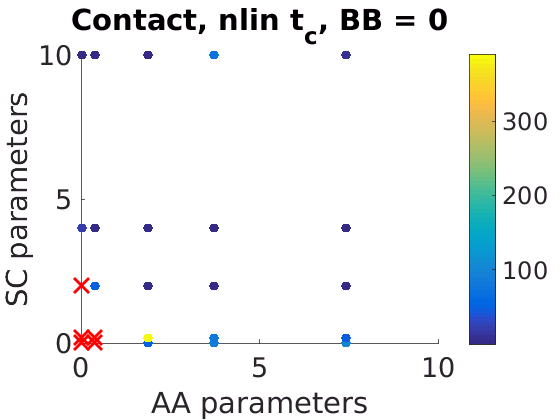


figure()
hold on
i1 = find(ctypemat(1:25,4) == 0);
inot = find(ctypemat(1:25,4) ~= 0);
plot(ctypemat(i1,1),ctypemat(i1,2),'rx','markersize',15,'linewidth',2)
scatter(ctypemat(inot,1),ctypemat(inot,2),50,contactMatrix(inot,3),'filled')
colorbar
set(gca,'fontsize',20)
xlabel('AA parameters')
ylabel('SC parameters')
title('Contact, nlin t_c, BB = 0')

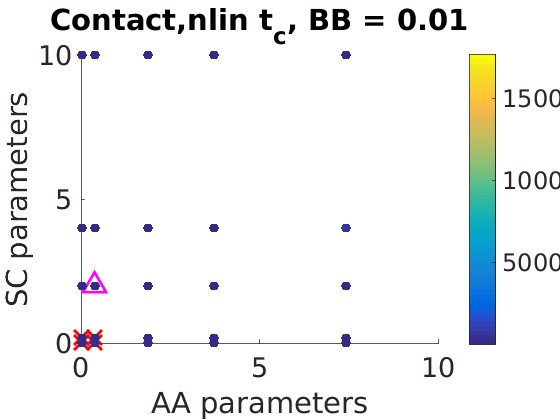


figure()
hold on
i1 = find(ctypemat(26:end,4) == 0)+25;
ianom = find(ctypemat(26:end,4)==4)+25;
inot = find((ctypemat(26:end,4) ~= 0)&(ctypemat(26:end,4)~=4))+25;
plot(ctypemat(i1,1),ctypemat(i1,2),'rx','markersize',15,'linewidth',2)
plot(ctypemat(ianom,1),ctypemat(ianom,2),'m^','markersize',15,'linewidth',2)
scatter(ctypemat(inot,1),ctypemat(inot,2),50,contactMatrix(inot,3),'filled')
colorbar
set(gca,'fontsize',20)
xlabel('AA parameters')
ylabel('SC parameters')
title('Contact,nlin t_c, BB = 0.01')

Try to put this together into a single t_c graph

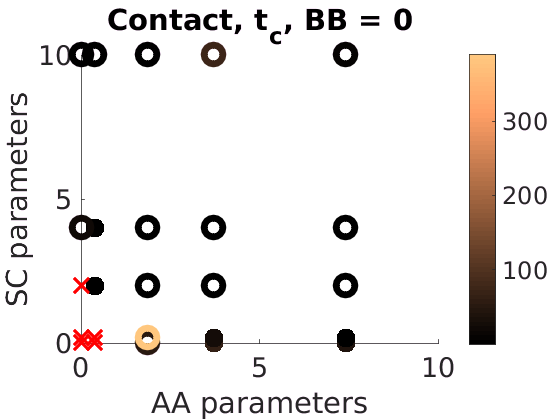

figure()
hold on
colormap copper
i1 = find(ctypemat(1:25,4) == 0);
inot = find((ctypemat(1:25,4) ~= 0) & (abs(contactMatrix(1:25,5))<1));
plot(ctypemat(i1,1),ctypemat(i1,2),'rx','markersize',15,'linewidth',2)
scatter(ctypemat(inot,1),ctypemat(inot,2),200,contactMatrix(inot,1),'filled')
colorbar

inot = find((ctypemat(1:25,4) ~= 0) & (abs(contactMatrix(1:25,5))>1));
plot(ctypemat(i1,1),ctypemat(i1,2),'rx','markersize',15,'linewidth',2)
scatter(ctypemat(inot,1),ctypemat(inot,2),200,contactMatrix(inot,3),'linewidth',5)
colorbar
set(gca,'fontsize',20)
xlabel('AA parameters')
ylabel('SC parameters')
title('Contact, t_c, BB = 0')

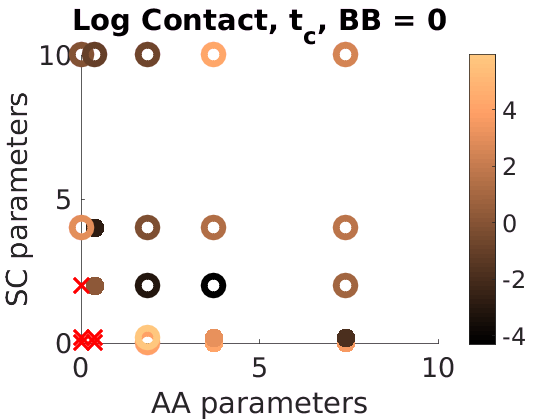


%log version
figure()
hold on
colormap copper
i1 = find(ctypemat(1:25,4) == 0);
inot = find((ctypemat(1:25,4) ~= 0) & (abs(contactMatrix(1:25,5))<1));
plot(ctypemat(i1,1),ctypemat(i1,2),'rx','markersize',15,'linewidth',2)
scatter(ctypemat(inot,1),ctypemat(inot,2),200,log(contactMatrix(inot,1)),'filled')
colorbar

inot = find((ctypemat(1:25,4) ~= 0) & (abs(contactMatrix(1:25,5))>1));
plot(ctypemat(i1,1),ctypemat(i1,2),'rx','markersize',15,'linewidth',2)
scatter(ctypemat(inot,1),ctypemat(inot,2),200,log(contactMatrix(inot,3)),'linewidth',5)
colorbar
set(gca,'fontsize',20)
xlabel('AA parameters')
ylabel('SC parameters')
title('Log Contact, t_c, BB = 0')

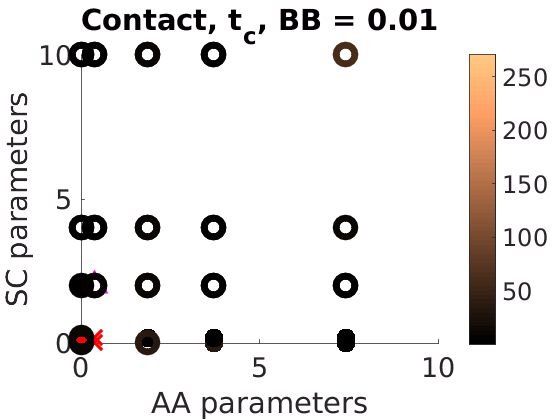

figure()
hold on
colormap copper
i1 = find(ctypemat(26:50,4) == 0)+25;
ianom = find(ctypemat(26:50,4)==4)+25;
inot = find((ctypemat(26:50,4) ~= 0) & (abs(contactMatrix(26:50,5))<1))+25;
plot(ctypemat(i1,1),ctypemat(i1,2),'rx','markersize',15,'linewidth',2)
plot(ctypemat(ianom,1),ctypemat(ianom,2),'m^','markersize',15,'linewidth',2)
scatter(ctypemat(inot,1),ctypemat(inot,2),200,contactMatrix(inot,1),'filled')
colorbar
inot = find((ctypemat(26:end,4) ~= 0) & (abs(contactMatrix(26:end,5))>1))+25;
plot(ctypemat(i1,1),ctypemat(i1,2),'rx','markersize',15,'linewidth',2)
scatter(ctypemat(inot,1),ctypemat(inot,2),200,contactMatrix(inot,3),'linewidth',5)
colorbar
set(gca,'fontsize',20)
xlabel('AA parameters')
ylabel('SC parameters')
title('Contact, t_c, BB = 0.01')

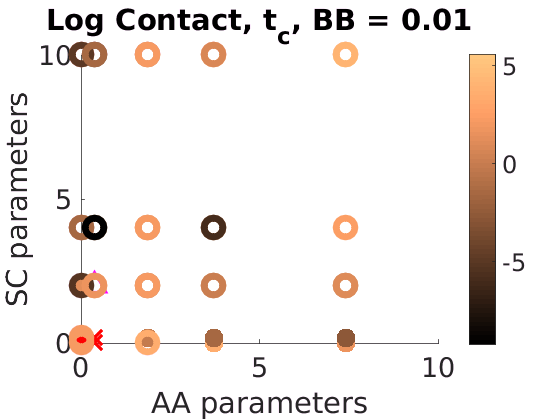


figure()
hold on
colormap copper
i1 = find(ctypemat(26:50,4) == 0)+25;
ianom = find(ctypemat(26:50,4)==4)+25;
inot = find((ctypemat(26:50,4) ~= 0) & (abs(contactMatrix(26:50,5))<1))+25;
plot(ctypemat(i1,1),ctypemat(i1,2),'rx','markersize',15,'linewidth',2)
plot(ctypemat(ianom,1),ctypemat(ianom,2),'m^','markersize',15,'linewidth',2)
scatter(ctypemat(inot,1),ctypemat(inot,2),200,log(contactMatrix(inot,1)),'filled')
colorbar
inot = find((ctypemat(26:end,4) ~= 0) & (abs(contactMatrix(26:end,5))>1))+25;
plot(ctypemat(i1,1),ctypemat(i1,2),'rx','markersize',15,'linewidth',2)
scatter(ctypemat(inot,1),ctypemat(inot,2),200,log(contactMatrix(inot,3)),'linewidth',5)
colorbar
set(gca,'fontsize',20)
xlabel('AA parameters')
ylabel('SC parameters')
title('Log Contact, t_c, BB = 0.01')

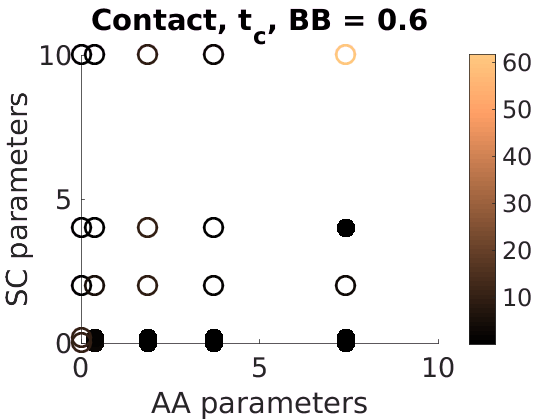

figure()
hold on
colormap copper
i1 = find(ctypemat(51:end,4) == 0)+50;
ianom = find(ctypemat(51:end,4)==4)+50;
inot = find((ctypemat(51:end,4) ~= 0) & (abs(contactMatrix(51:end,5))<1))+50;
plot(ctypemat(i1,1),ctypemat(i1,2),'rx','markersize',15,'linewidth',2)
plot(ctypemat(ianom,1),ctypemat(ianom,2),'m^','markersize',15,'linewidth',2)
scatter(ctypemat(inot,1),ctypemat(inot,2),200,contactMatrix(inot,1),'filled')
colorbar
inot = find((ctypemat(51:end,4) ~= 0) & (abs(contactMatrix(51:end,5))>1))+50;
plot(ctypemat(i1,1),ctypemat(i1,2),'rx','markersize',15,'linewidth',2)
scatter(ctypemat(inot,1),ctypemat(inot,2),200,contactMatrix(inot,3),'linewidth',2)
colorbar
set(gca,'fontsize',20)
xlabel('AA parameters')
ylabel('SC parameters')
title('Contact, t_c, BB = 0.6')